# Embedded AI: Hands-on Workshop

## Environment Setup

1.Create a working folder containing two parts in the MATLAB working directory. The default will be "C:\Users\<your username>\Documents\MATLAB\Hands-on workshop".

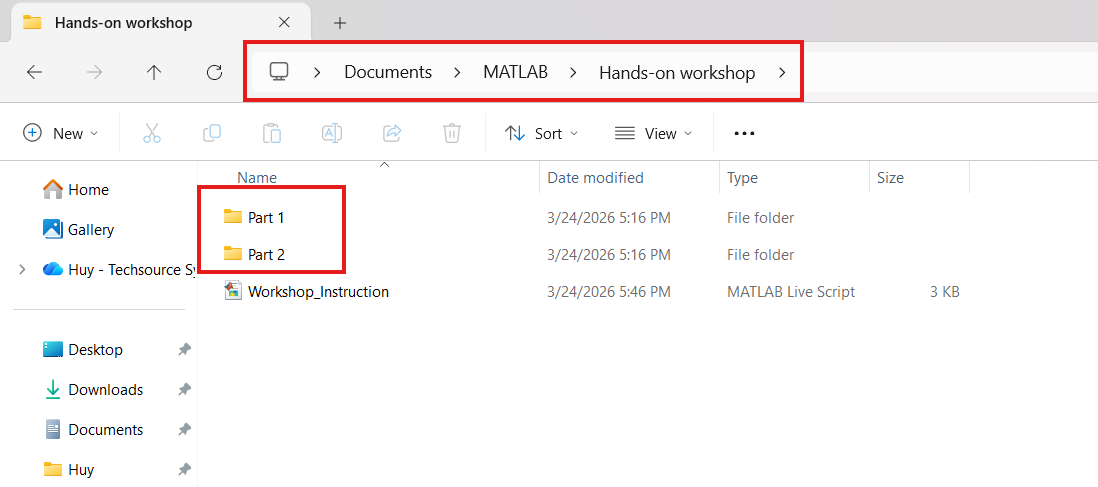

2.Copy a zip file download from Github to Part 2 folder and extract.

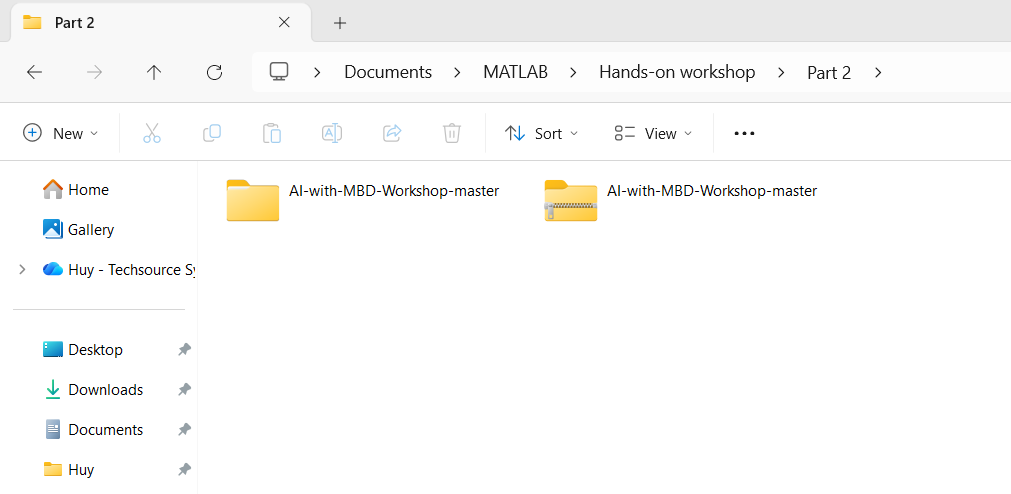

3.Add Hands-on workshop folder to MATLAB Path. Select Add Folder with Subfolders then navigate to the "Hands-on workshop" folder then click "Apply".

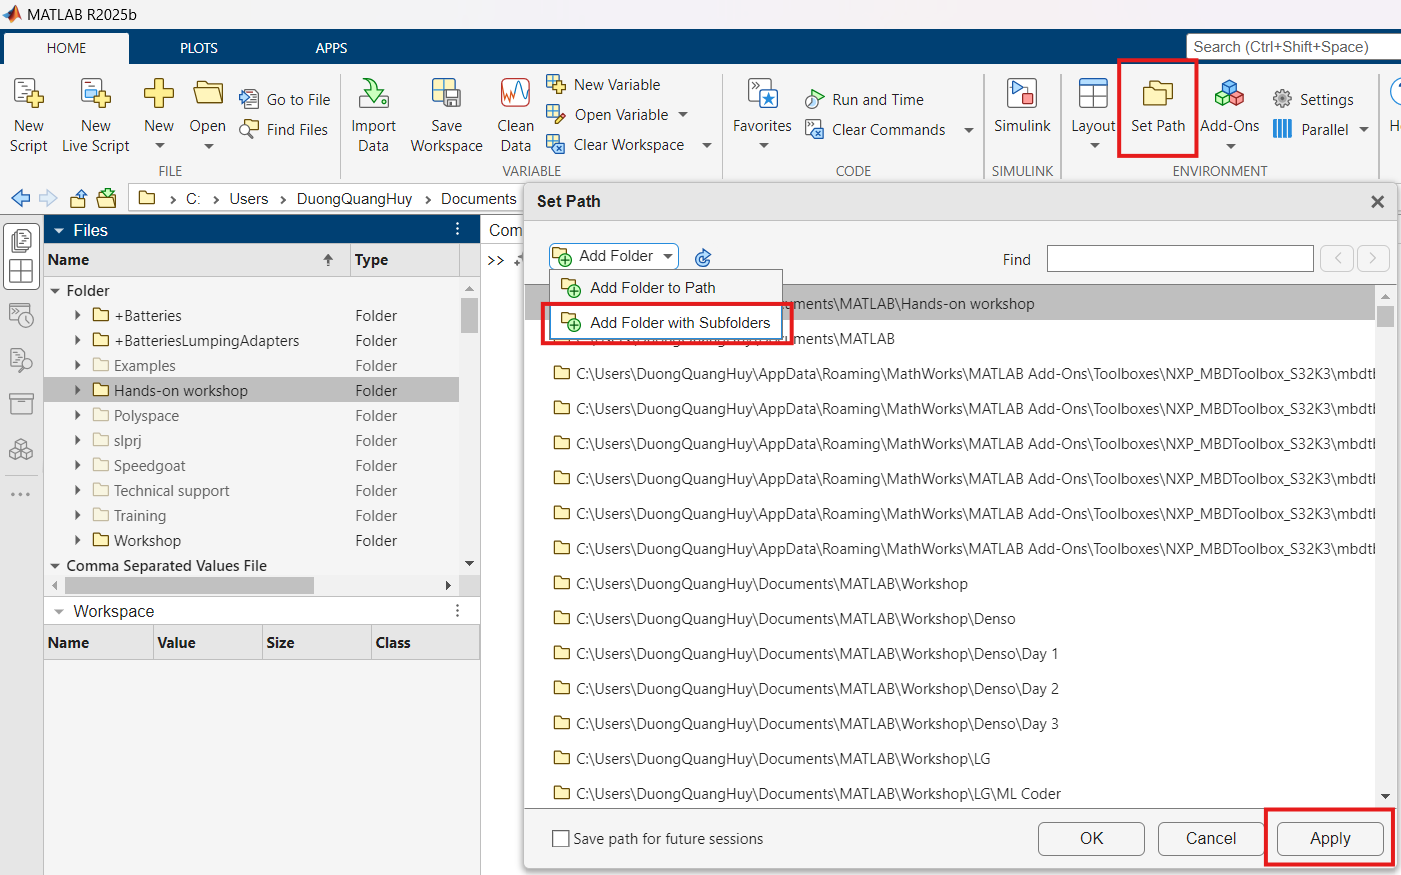

## Part 1: Plant modeling with Simulink and Simscape

1.Open MATLAB and Simulink

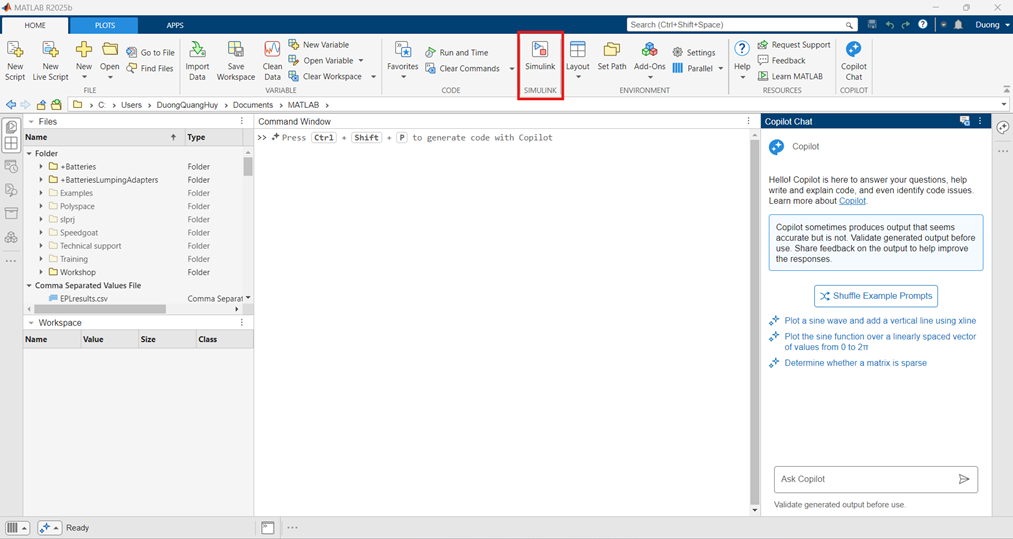

2.Click “Create Model” tocreate a new blank model

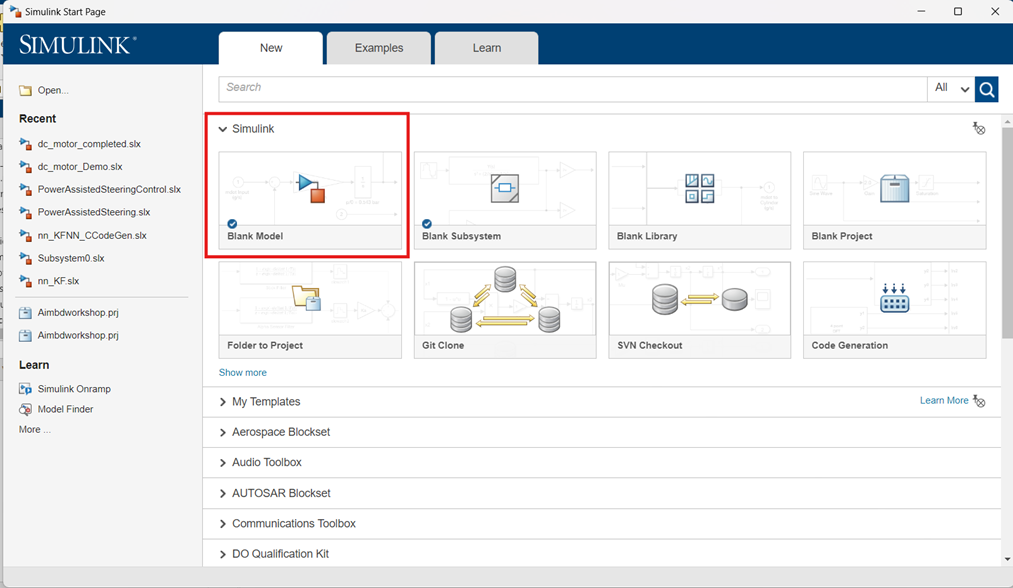

3.Drag and drop 2 “integrator” block from Library Browser → Simulink → Continuous

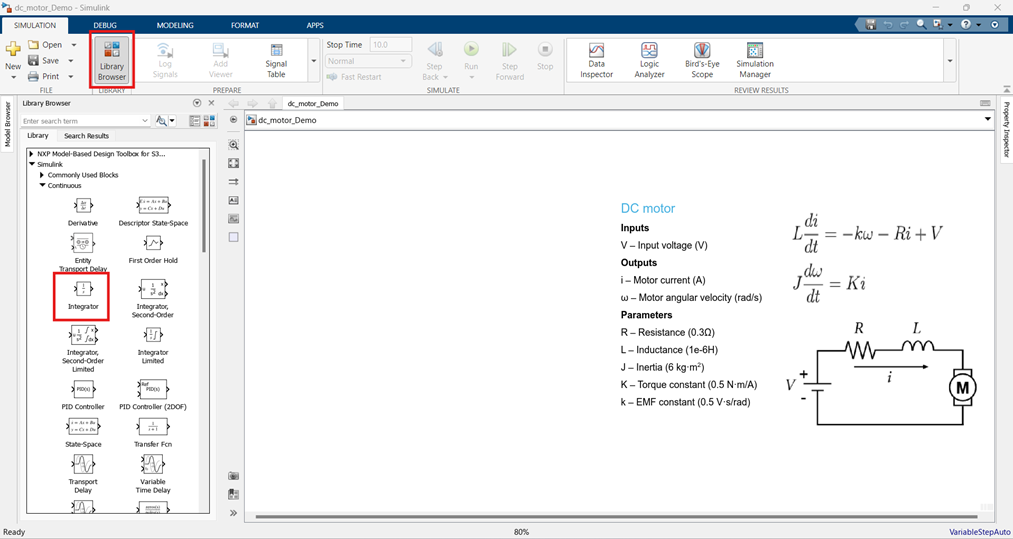

4.Create input voltage by insert “Step” block from Library Browser → Simulink → Sources. Double click to step block and change the final value to 20.

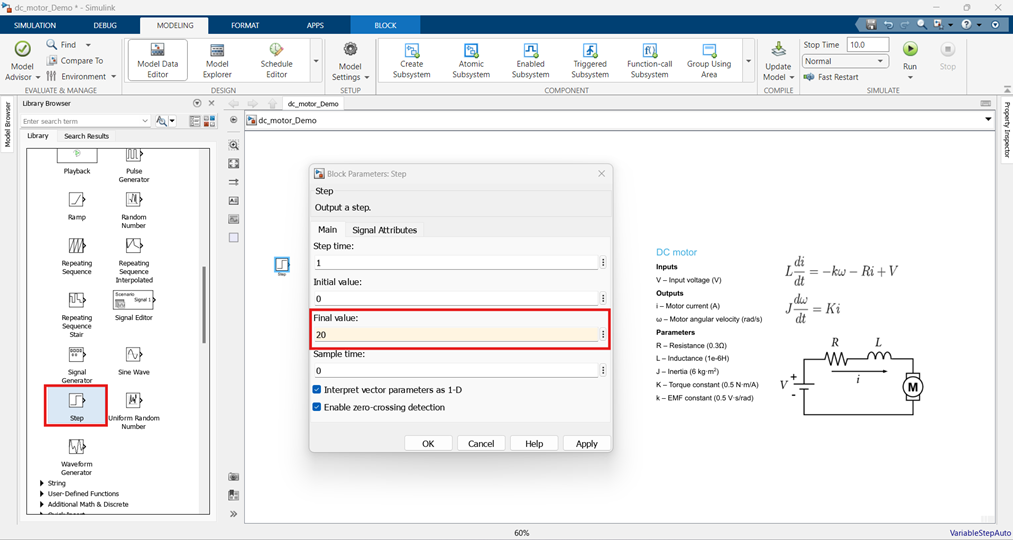

5.Create mathematical operations by insert 1 “Add” block and 3 “Gain” from Library Browser → Simulink → Math Operations. Double click to add block and change the list of signs to “+--” to follow the equation. Rename the three Gain blocks to R, k, and L respectively.

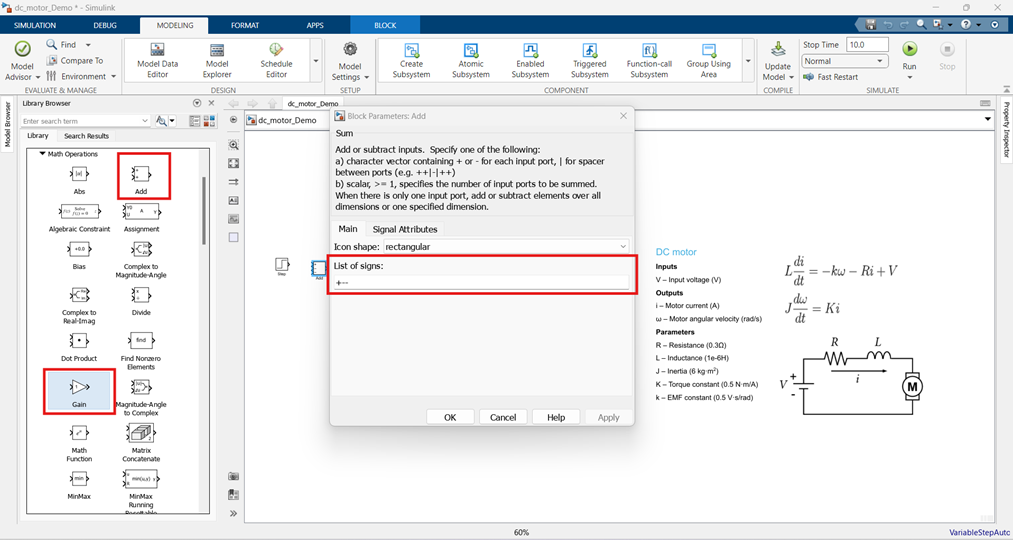

6.Double click to R, k, L block to change the value follow in the parameter. Note that for L, we have to move terms to the other side to divide, so block L must be converted to 1/1e-6.

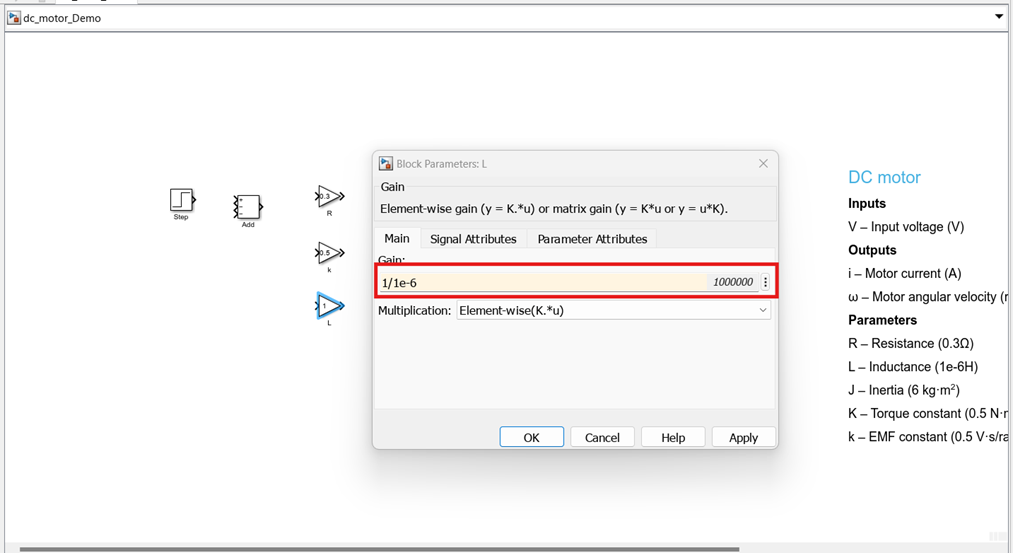

7.Connect the blocks to create the first equation.

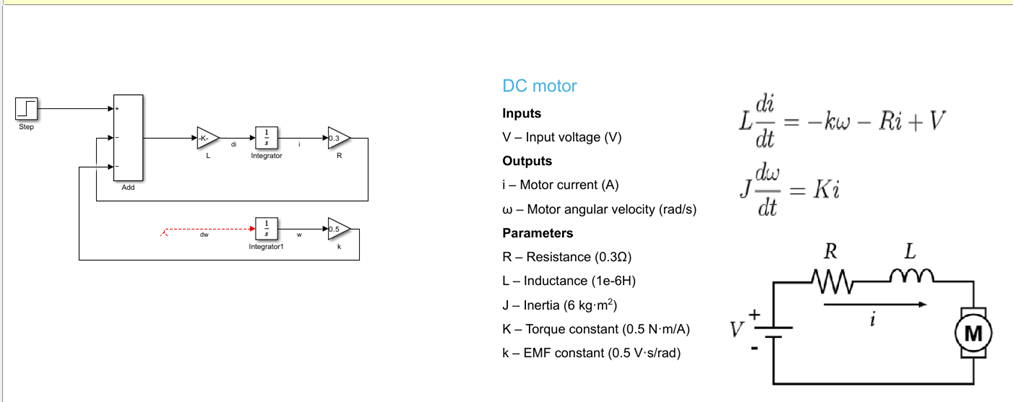

8.With the second equation, we can add two gain blocks, K and J, separately, or we can combine them into one block and define it as the K/J calculation within the formula. 

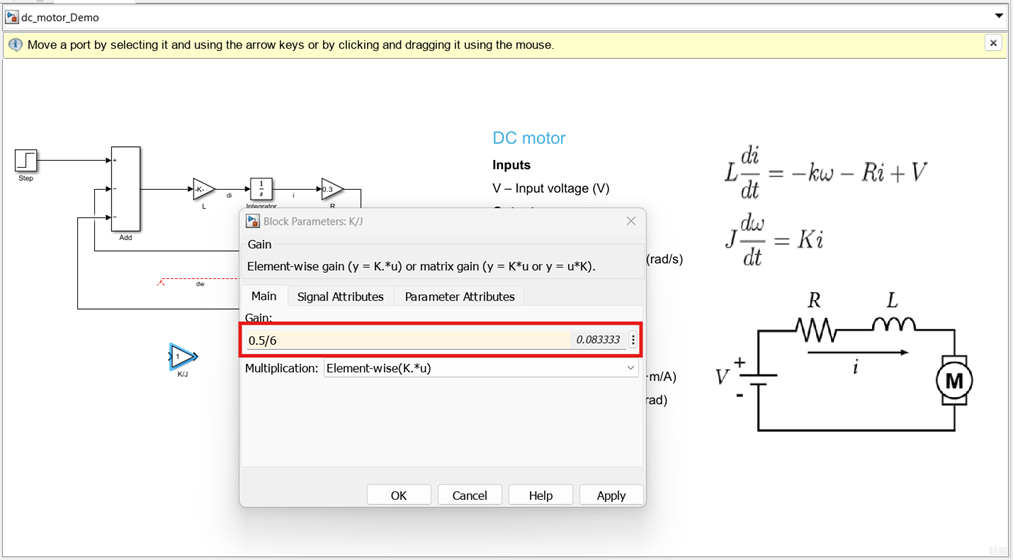

9.Connect the block to complete the second equation.

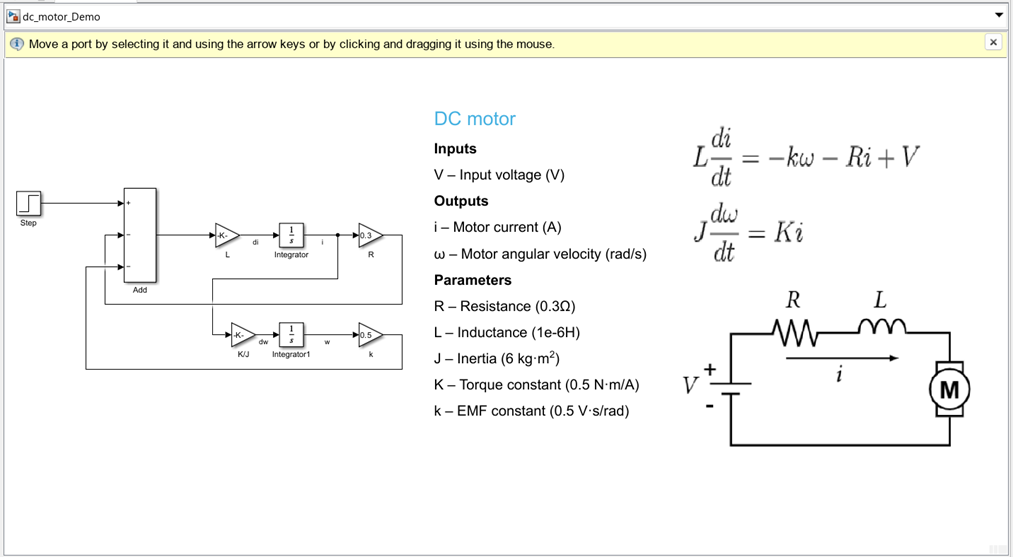

10.To see the result of the simulation, add a “Scope” block from Library Browser→ Simulink → Sinks. Connect motor current and velocity to the scope.

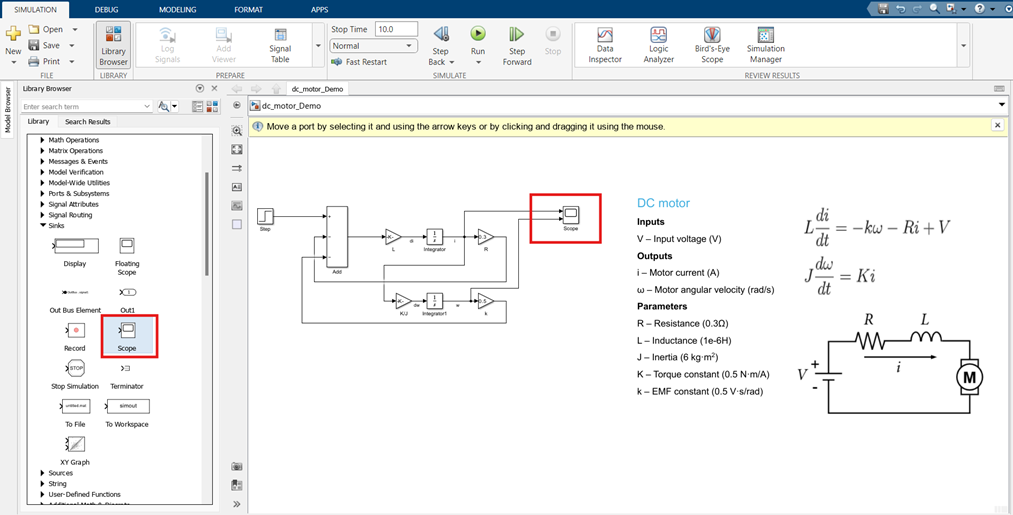

11.Run the simulation and double click to scope block to see the result.

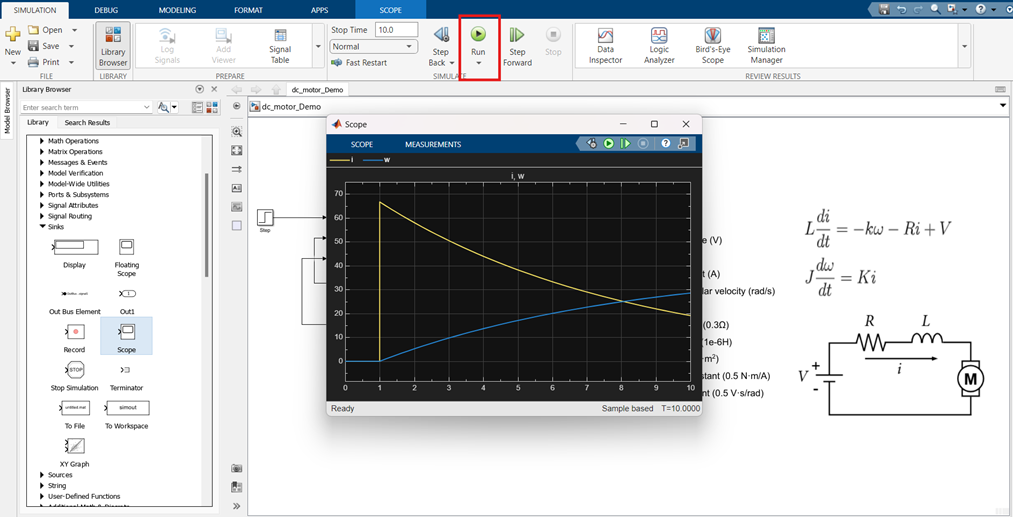

12.Insert the electrical foundation element “Resistor”, “Inductor”, “Electrical Reference”, “Rotational Electromechanical Converter” from Library Browser → Simscape → Foundation Library → Electrical → Electrical Elements to the canvas. Double click to “Resistor”, “Inductor”, “Rotational Electromechanical Converter” block to change the value follow in the parameter.

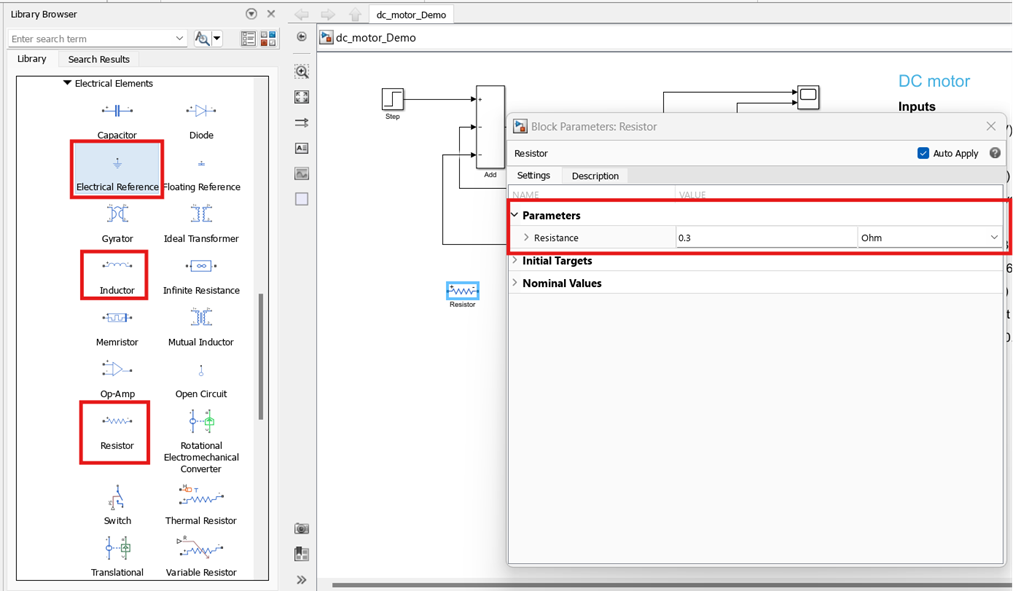

13.Add block “Controlled Voltage Source” from Library Browser → Simscape → Foundation Library → Electrical → Electrical Sources to generate the input voltage and block “Current Sensor” from Library Browser → Simscape → Foundation Library → Electrical → Electrical Sensors to measure the output current.

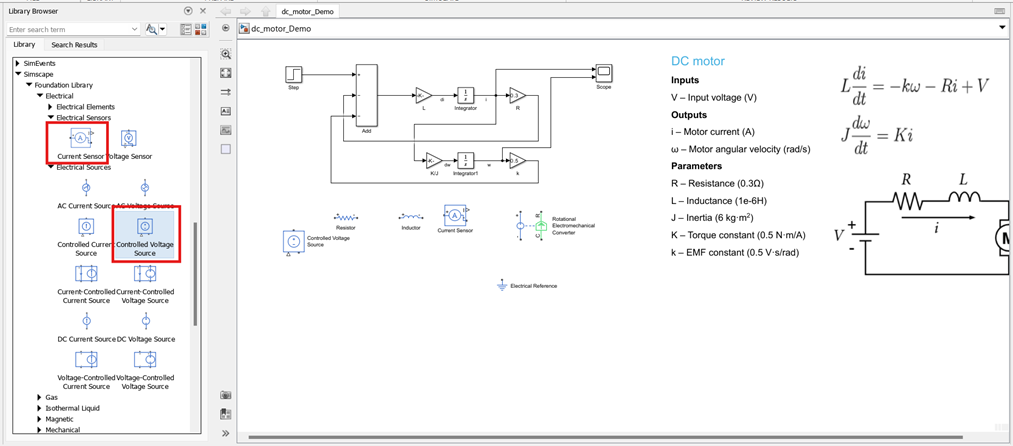1

14.To complete the mechanical part of the motor, add block “Inertia”, “Mechanical Rotational Reference” from Library Browser → Simscape → Foundation Library → Mechanical → RotationalElements to the canvas. Double click to “Inertia” block to change the value follow in the parameter.

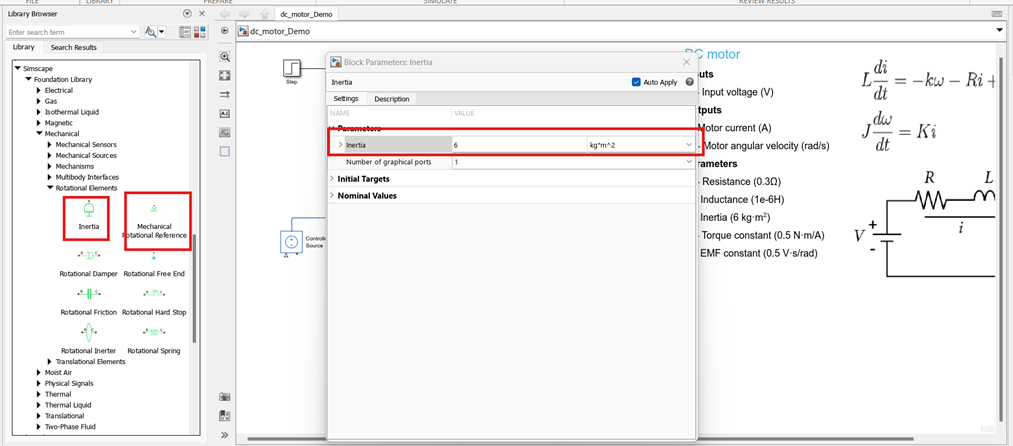

15.Add block “Ideal Rotational Motion Sensor” from Library Browser → Simscape → Foundation Library → Mechanical → Mechanical Sensors to measure the motor velocity. Then connect all the block to make a motor model.

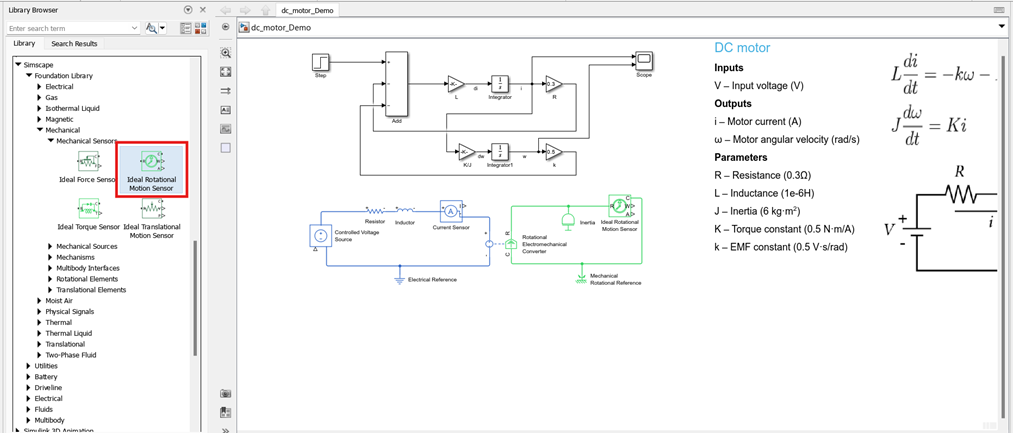

16.Add block “Simulink-PS Converter”, 2 block “PS-Simulink Converter”, “Solver Configuration” to connect Simscape model with Simulink input/output. Then connect with simulink Step block and scope block.

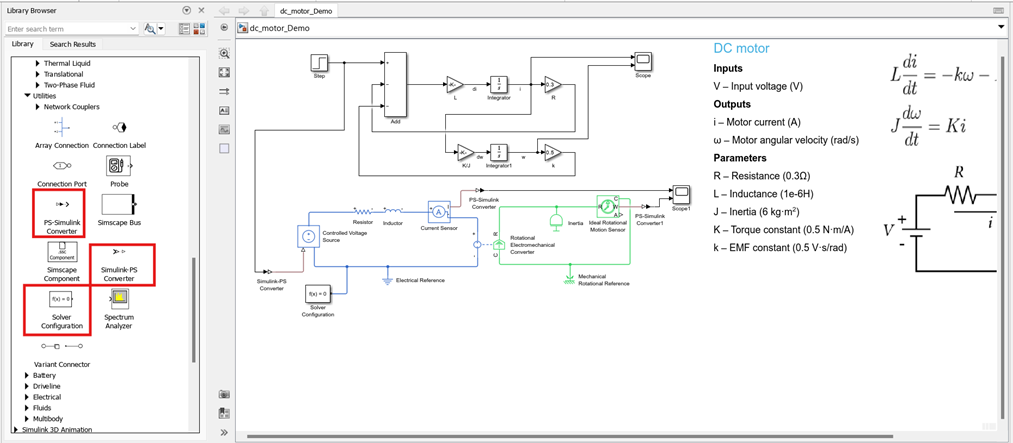

17.Run the simulation and double click to scope block to see the result

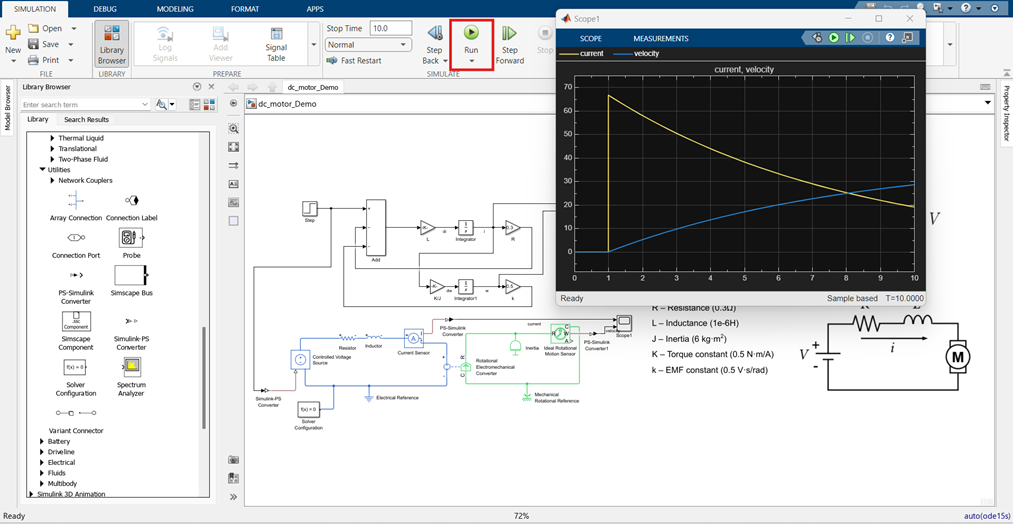

## Part 2: Integrate AI models into Simulink for simulation and code generation.

1.Go in the “AI-with-MBD-Workshop-master” folder. Double click to open the project.

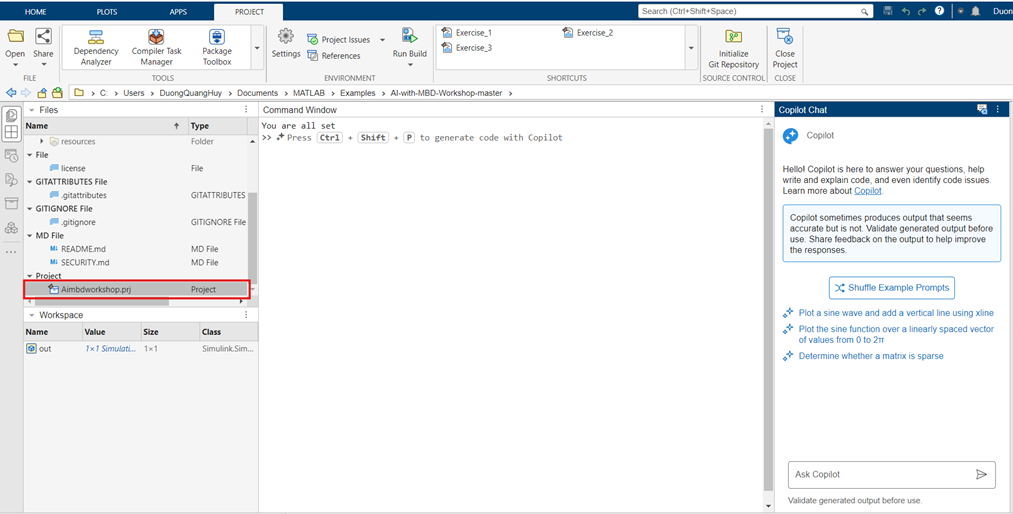

2.Unzip the TensorFlow™ Model

The TensorFlow model is available in a zipped folder. Unzip the folder to access it in MATLAB. 

clear
proj = currentProject;
unzip(helper.getPyModelFolder,helper.getCurrPartFolder("P2"))

3.Import Network using Deep Network Designer

Launch the Deep Network Designer:

deepNetworkDesigner

Click on "Import" in the "From TensorFlow" option from the Start Page. If you've not installed **Deep Learning Toolbox Converter for TensorFlow Models**, you can first click the "Install" button and then click on "Import" after the installation is complete.

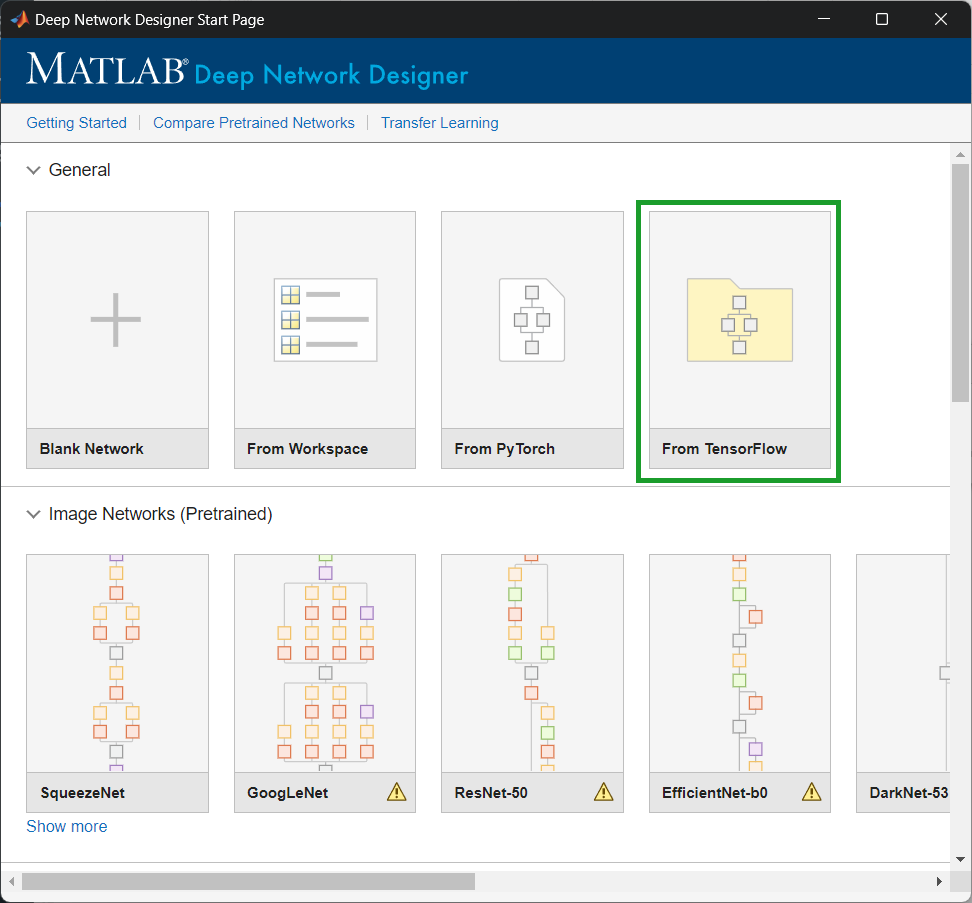

Select the **folder** that contains the TensorFlow model. Click "Import".

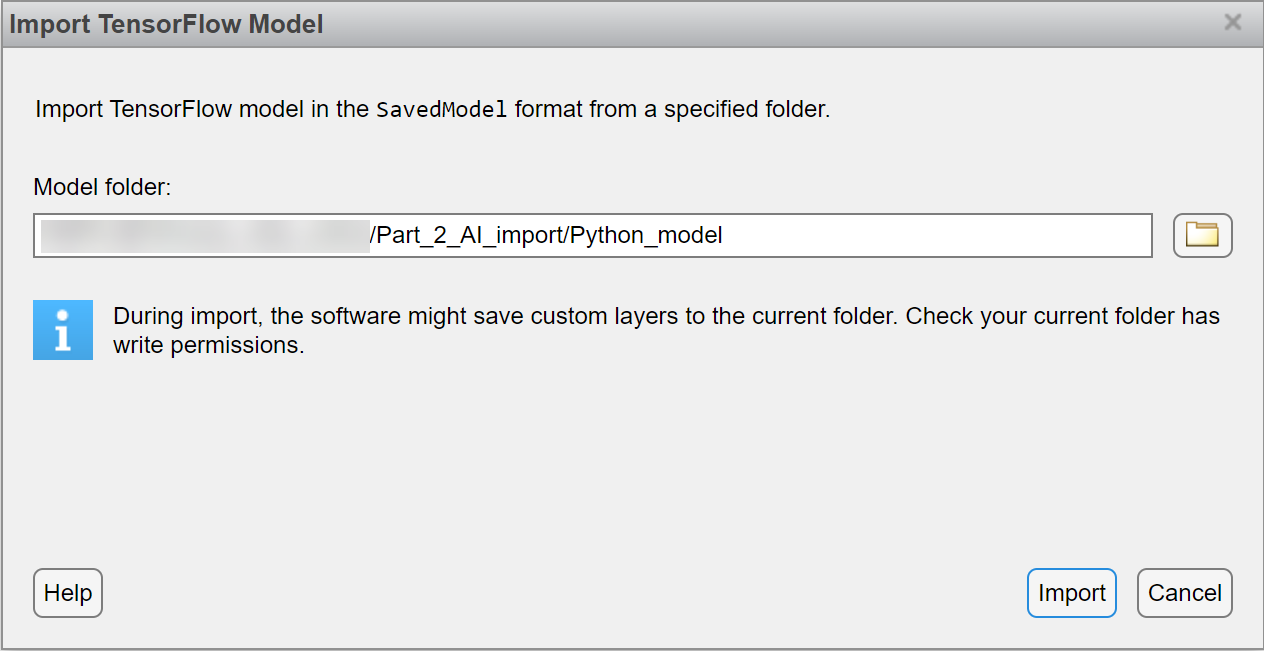

Import Progress is showned in the menu.

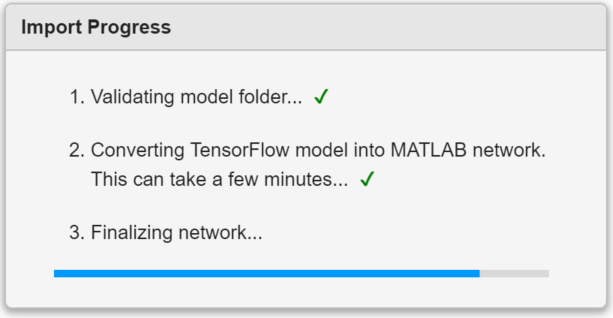

4.Review Network Design

After import is complete, click on the "Designer" tab to inspect the network architecture and confirm properties of individual layers.

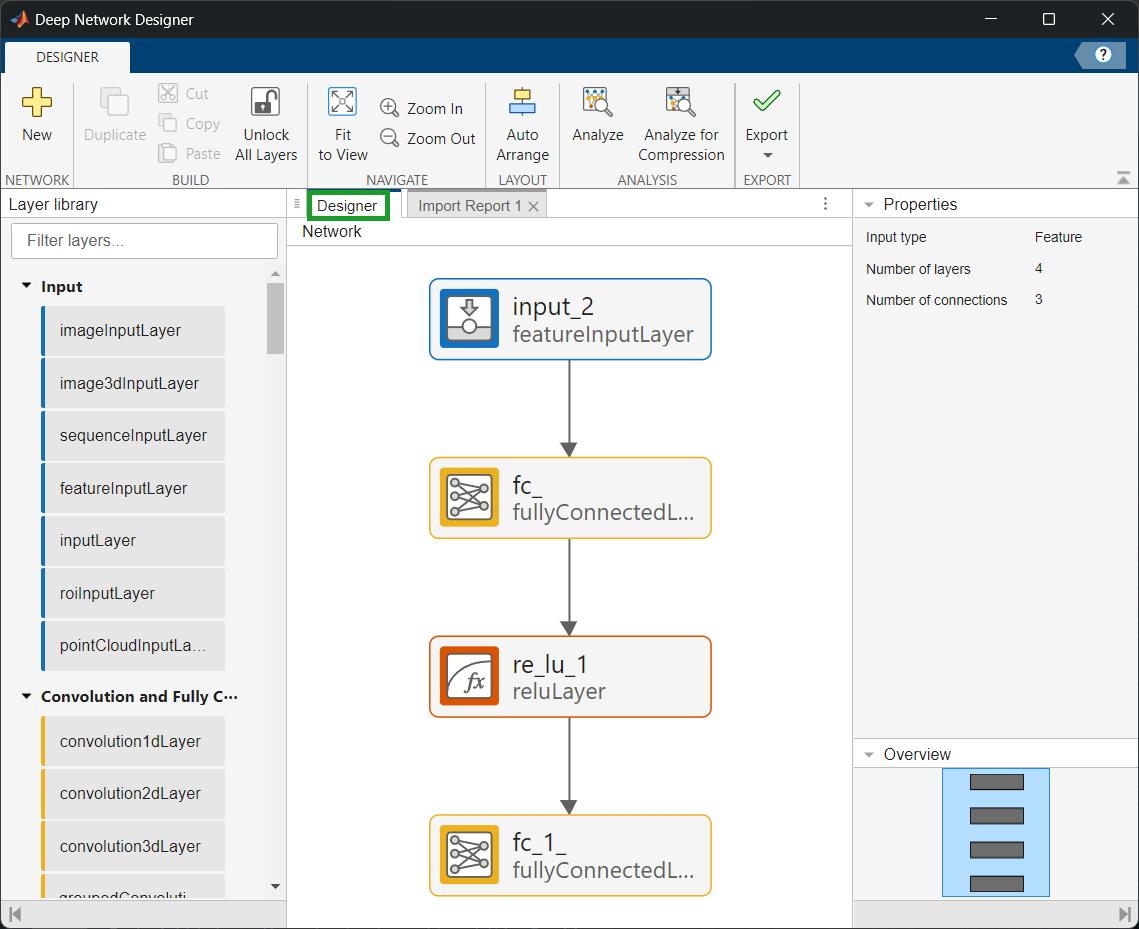

5.Export AI Model

Export the AI model to Simulink from the toolstrip.

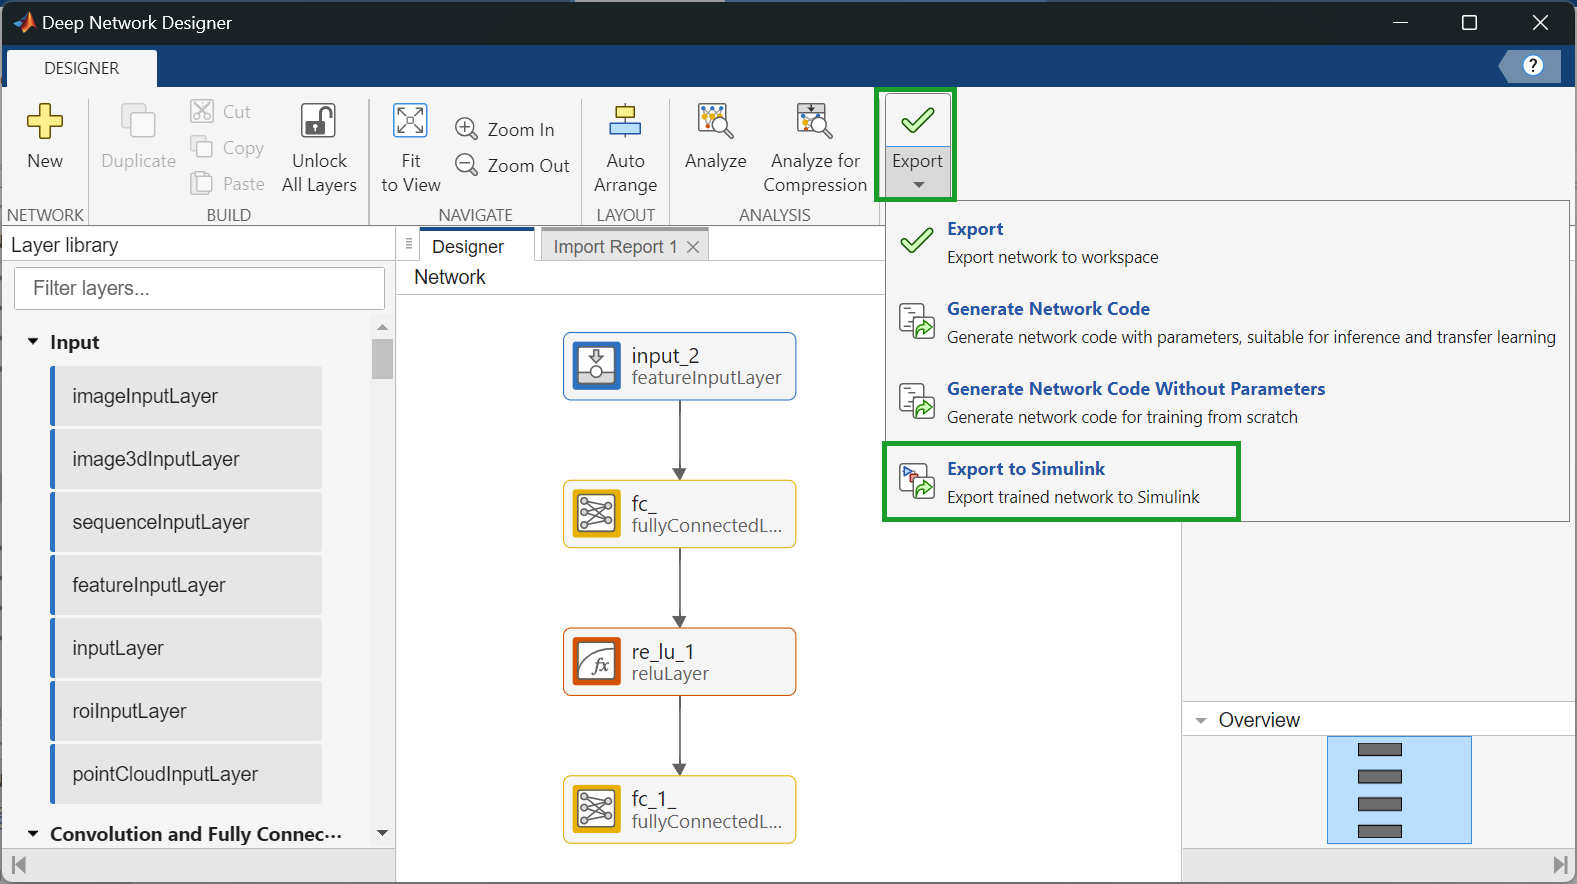

The app has two types of Simulink export:

- Export to a single network block, for example, a Predict block

- Export to multiple layer blocks

For small networks with all layers supported as layer blocks, exporting to layer blocks is recommended. For large networks or networks with layers not supported as layer blocks, exporting to a single network block is recommended. You can experiment with both options. For this workshop, we will use a single network block for all our exercise

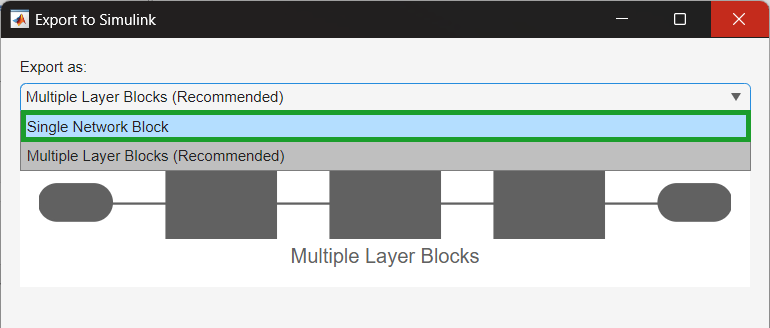

Keep the default location and click Export.

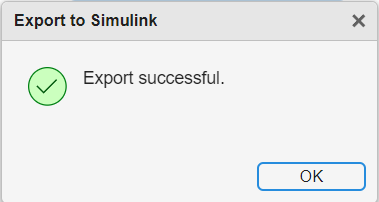

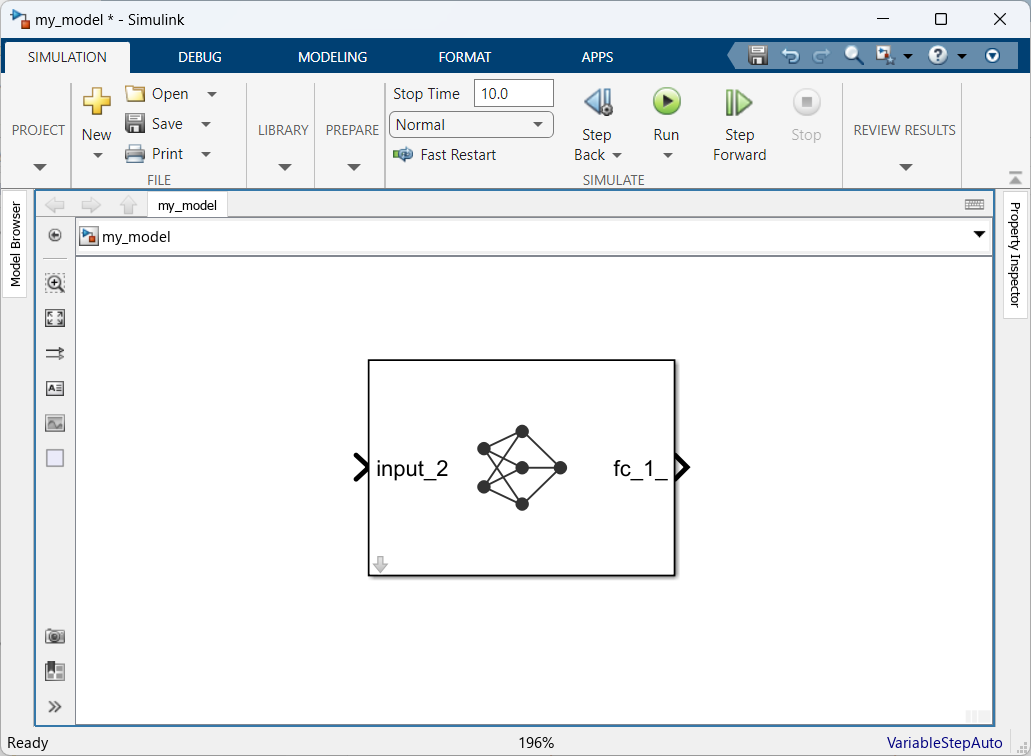

6.Specify the input format in the Predict block

Note the AI model is automatically saved as a MAT file along with the SImulink model .

**To Do:** As we did in the previous exercise, double click on the **Predict Block** to open the **Block Parameters** menu. Specify the **Input data format** as "CB" - this means the input data is formatted as *c*-by-*n* array, where *c* is the number of features, and *n* is the number of observations. 

**7.Generate the Inputs for Simulink**

In Simulink, there are several ways how you can import data: "From Workspace" block, "Inport" block, "From File" block and others. We are going to use "From Workspace" blocks. We need to generate the inputs for Simulink in the correct format and we can use the left-out test data set.

dataFolder = helper.getDataFolder();
testFile = fullfile(dataFolder,"Test","01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
S = load(testFile);
steps = size(S.X,2);
t = (0:(steps-1))';
X_in = timeseries(single(S.X'), t);
true_SOC = timeseries(single(S.Y'), t);

8.Configure Model Parameters for Simulations

Open the **Configuration Parameters** dialog (or Ctrl+E) and set **Stop time **to the workspace variable named "steps" (which is the total number of simulation steps; this variable will be generated in a later section), and set the solver to "Fixed-step" and "Discrete" with a fundamental step size of 1:

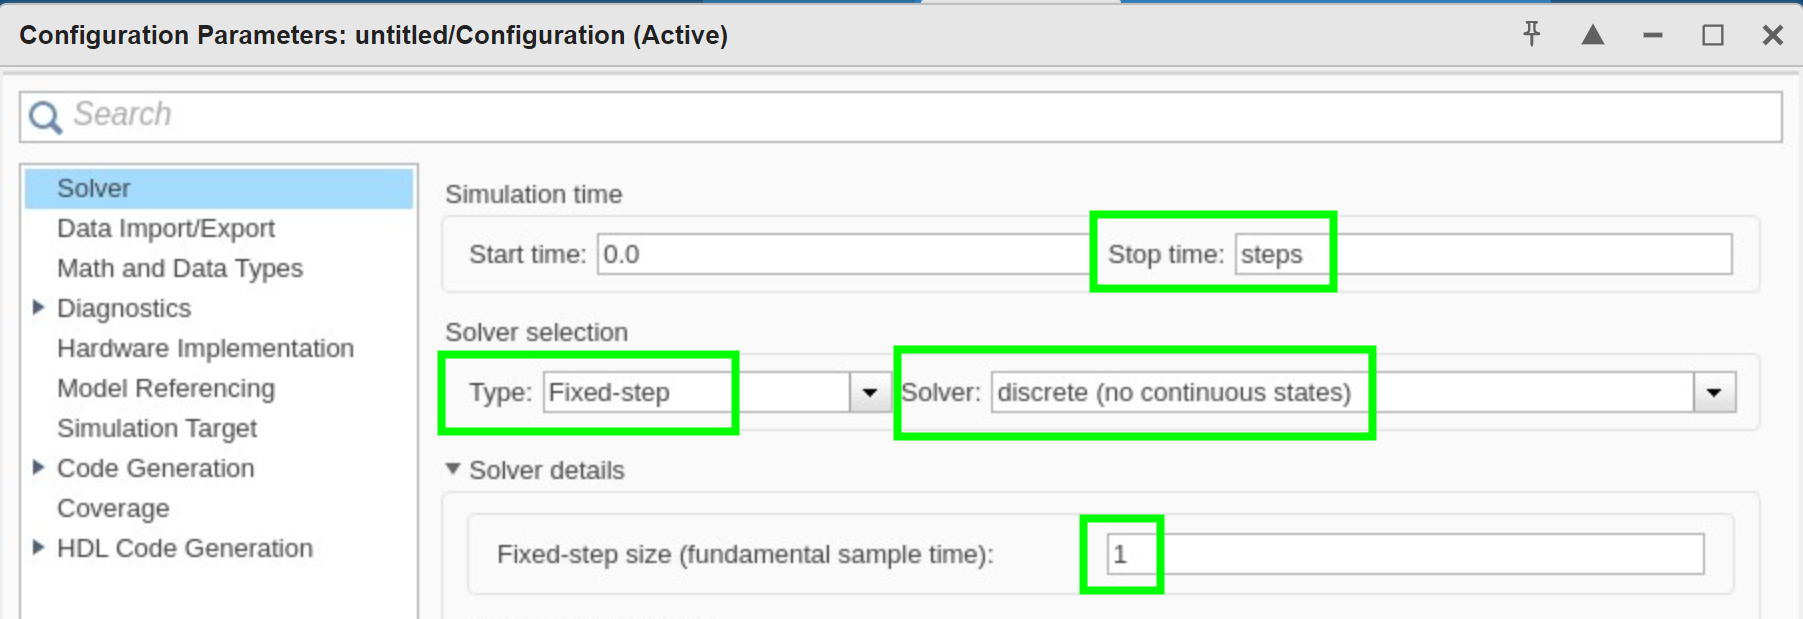

9.Connect the Model

Add two "From Workspace" blocks with "X_in" and "true_SOC" for the data variables, respectively. Connect the "X_in" input to the "Predict" block. Connect the "true_SOC" input to a "Scope" block in the following way:

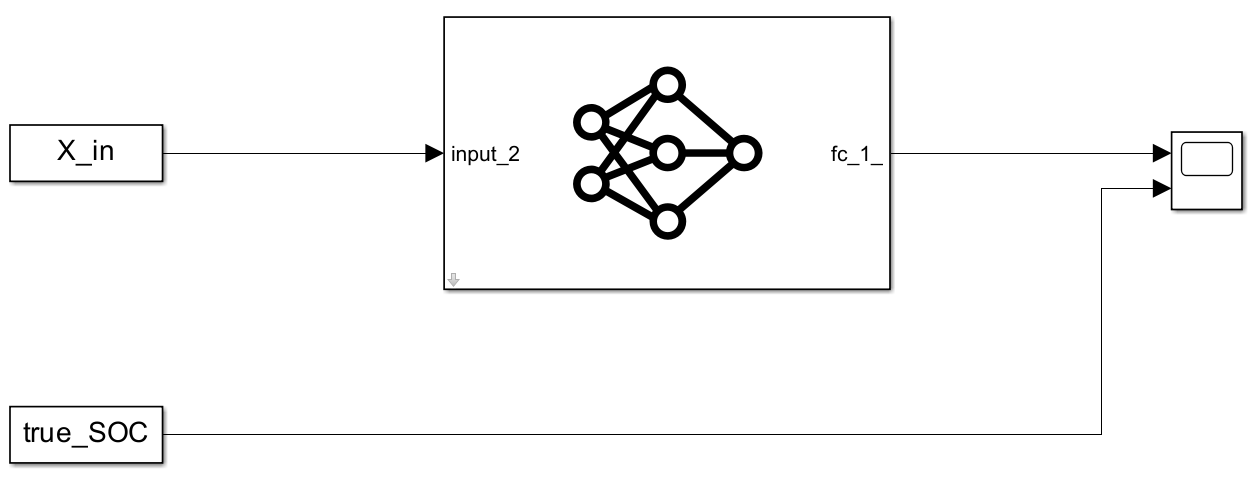

10.Run the Simulink Model

Now we can simulate the model by clicking the "Run" button and double-click on the "Scope" block to inspect simulation results:

(You may check `exampleModel_TF_import.slx` if you run into any issues)

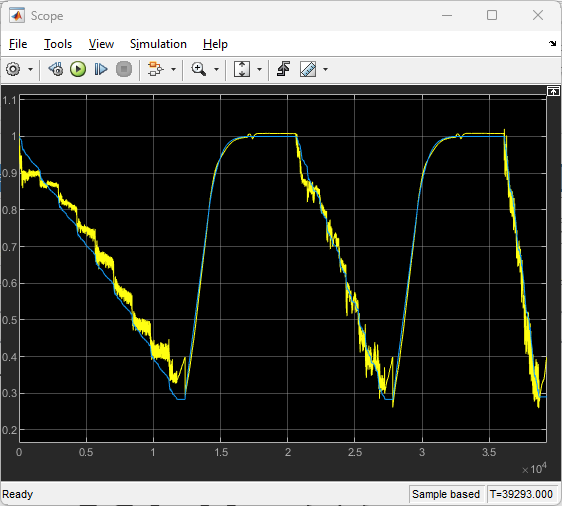

11.Load Previously Trained LSTM Network

clear
origFileName = 'DLmodel_ref_stackedLSTM.mat';
projectedFileName = 'DLmodel_ref_stackedLSTM_Projected.mat';
load(origFileName);
recurrentNet.Layers

ans =   7×1 Layer array with layers:

     1   'sequenceinput'   Sequence Input    Sequence input with 3 dimensions
     2   'lstm_1'          LSTM              LSTM with 256 hidden units
     3   'dropout_1'       Dropout           20% dropout
     4   'lstm_2'          LSTM              LSTM with 128 hidden units
     5   'dropout_2'       Dropout           20% dropout
     6   'fc'              Fully Connected   1 fully connected layer
     7   'layer'           Sigmoid           sigmoid

analyzeNetwork(recurrentNet)

Note that the original LSTM network has 463.4k learnables. By default, in MATLAB, DL network learnables are stored in single-precision, floating-point format (fp32). At 4 bytes (32 bits) per learnable, this translates to a total learnables size of **~1.85 MB**. 

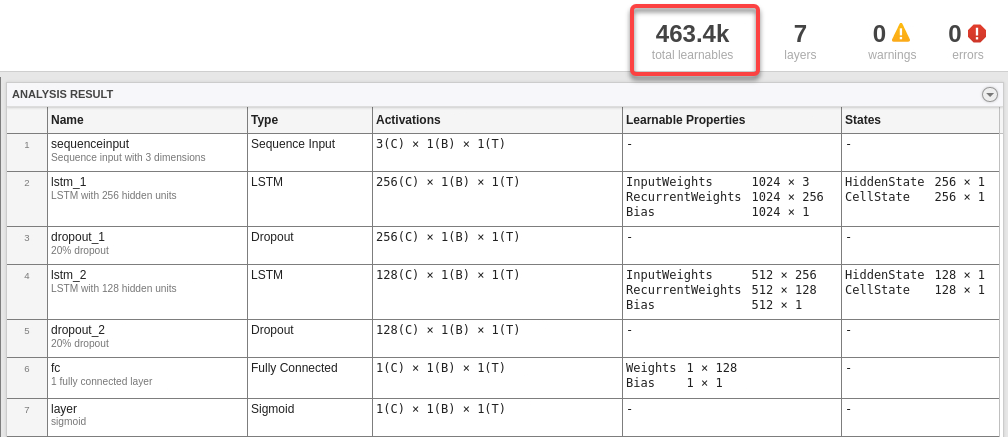

12.Data Preparation

dataFolder = helper.getDataFolder;
chunkSize = 500;
numFeatures = 3;

trainingFile = fullfile(dataFolder,"Train","TRAIN_LGHG2@n10degC_to_25degC_Norm_5Inputs.mat");
[XTrain,YTrain] = helper.setupDataLSTM(trainingFile,chunkSize,numFeatures);
validationFile = fullfile(dataFolder,"Validation", "01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
[XVal,YVal] = helper.setupDataLSTM(validationFile,chunkSize,numFeatures);

for i = 1:numel(XTrain)
    XTrain{i} = XTrain{i}.';
    YTrain{i} = YTrain{i}.';
end
for i = 1:numel(XVal)
    XVal{i} = XVal{i}.';
    YVal{i} = YVal{i}.';
end

13.Model Compression - Projection

**Understanding network compression with projection**

To compress a neural network, MATLAB uses a technique that involves projecting the network's layers into smaller parameter subspaces, thereby reducing the memory footprint of the model. This is done by introducing projector matrices that transform the learnable parameters into a lower-dimensional space without significantly compromising prediction accuracy. A projected deep neural network can also exhibit faster forward passes (inference) or deployed to embedded hardware using library-free C or C++ code generation, making projection a powerful technique for both reducing memory requirements and boosting throughput. To learn more about the algorithm based on principal component analysis (PCA) underlying network projection, refer to [this page](https://www.mathworks.com/company/newsletters/articles/compressing-neural-networks-using-network-projection.html).

As of R2024a, the following network layers support compression with projection:

- `convolution2dLayer`

- `fullyConnectedLayer`

- `lstmLayer`

- `gruLayer`

**Explore Compression Levels**

A trade-off exists between the amount of compression we apply to the network and its accuracy. In general, reducing the number of learnable parameters in a pretrained network will reduce its accuracy. Let's experiment by compressing the network with projection by a range of increasing amounts. To do this, let's iterate over 20 values of the `ExplainedVarianceGoal` in put argument to the `compressNetworkUsingProjection `function and plot the results. Then, we can decide on a worthwhile trade-off point between network size and accuracy.

The explained variance of a network details how well the space of network activations can capture the underlying features of the data. To explore different amounts of compression, you can iterate over different values of the ExplainedVarianceGoal option of the compressNetworkUsingProjection function and compare the results.

mbSize = 48;
mbq = minibatchqueue(...
    arrayDatastore(XTrain(1:10:end-1),OutputType="same",ReadSize=mbSize),...
    MiniBatchSize=mbSize,...
    MiniBatchFormat="TCB",...
    MiniBatchFcn=@(X) cat(3,X{:}));

npca = neuronPCA(recurrentNet, mbq); % Create Neuron Principal Component Analysis (PCA) object

Using solver mode "direct".
neuronPCA analyzed 3 layers: "lstm_1","lstm_2","fc"


numValues = 20;
explainedVarGoal = 1 - logspace(-3,0,numValues);
explainedVariance = zeros(1,numValues);
learnablesReduction = zeros(1,numValues);
accuracy = zeros(1,numValues);

S = load(validationFile);
XTest = S.X(1:numFeatures,:);
YTest = S.Y';

for i = 1:numel(explainedVarGoal)
    varianceGoal = explainedVarGoal(i);

    [dlnetProjected,info] = compressNetworkUsingProjection(recurrentNet, npca, ...
        ExplainedVarianceGoal=varianceGoal, ...
        VerbosityLevel="off");

    explainedVariance(i) = info.ExplainedVariance;
    learnablesReduction(i) = info.LearnablesReduction;
    
    YPredProjected = predict(dlnetProjected, dlarray(XTest,"CTB"));
    YPredProjected = extractdata(YPredProjected(:));
    accuracy(i) = sqrt(mean((YTest - YPredProjected).^2));
end

Visualize the effect of the different settings of the explained variance goal.

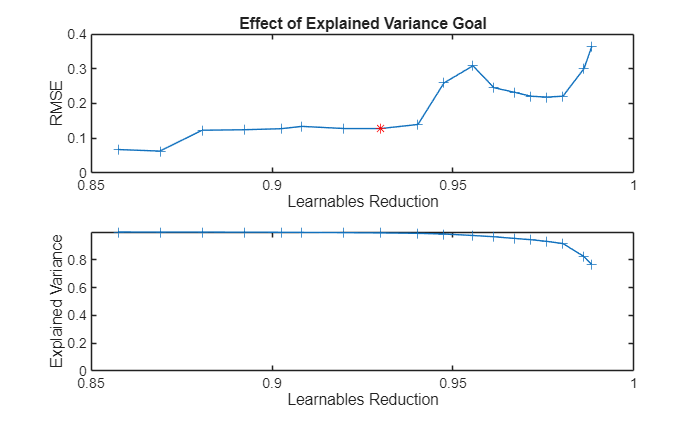

figure
tiledlayout("flow")
nexttile
plot(learnablesReduction,accuracy,'+-')
hold on
plot(0.93, 0.128, 'r*')
xlabel("Learnables Reduction")
ylabel("RMSE")
title("Effect of Explained Variance Goal")

nexttile
plot(learnablesReduction,explainedVariance,'+-')
ylim([0 inf])
ylabel("Explained Variance")
xlabel("Learnables Reduction")

The graph shows that an increase in learnable reduction has a corresponding increase in RMSE (decreace in accuracy). A learnable reduction value of around **93%** shows a good compromise between explained variance and RMSE.

14.Compress stacked-LSTM via Projection of Layers

dlnetProjected = compressNetworkUsingProjection(recurrentNet, mbq, LearnablesReductionGoal = 0.93); % project network with 93% learnables reduction value

Compressed network has 93.0% fewer learnable parameters.
Projection compressed 3 layers: "lstm_1","lstm_2","fc"


analyzeNetwork(dlnetProjected)

The new, projected network has 32.3k learnables. Still stored in `fp32`, the size now amounts to **~0.13 MB**. 

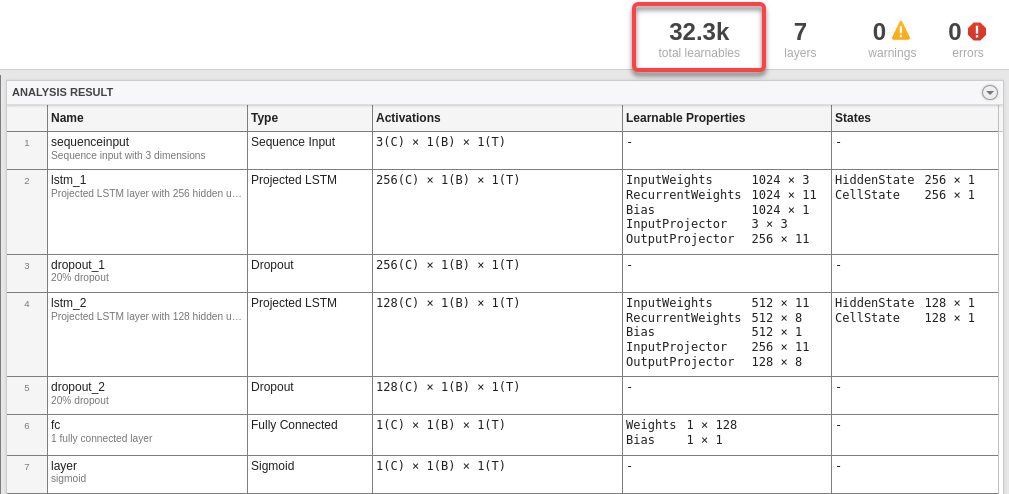

15.Fine-tune Compressed Stacked-LSTM Network

Starting with a pretrained network, the projected network equivalent can be directly computed as demonstrated above. Although a high degree of data covariance is retained, the network may need fine-tuning as accuracy can drop following the compression. This could be a result of higher order nonlinear relations between neurons in the network needing to readjust given the linear transformation or a compounding effect if many layers are projected at once. The projected model provides a good initialization for fine-tuning by further retraining. The fine-tune retraining typically takes far fewer epochs for the accuracy to plateau and can largely recover, in many cases, the accuracy of the original network.

doTraining = false; % Set to true if you would like to run fine-tuning, otherwise, the script will load a fine-tuned model from file below

if doTraining  

    options = trainingOptions("adam", ...
        MaxEpochs = 300,...
        ExecutionEnvironment = "auto", ...
        InitialLearnRate = 1e-2, ...
        LearnRateSchedule = "piecewise",...
        LearnRateDropPeriod = 120,...
        LearnRateDropFactor = 0.1,...
        GradientThreshold = 1,...
        Shuffle = "every-epoch",...
        Verbose = false,...
        ValidationFrequency = 10, ...
        MiniBatchSize = 64, ...
        Plots = "training-progress", ...
        ValidationData = {XVal,YVal});
    
    recurrentNetProjected = trainnet(XTrain,YTrain,dlnetProjected,"mse",options);
else
    load(projectedFileName);
end

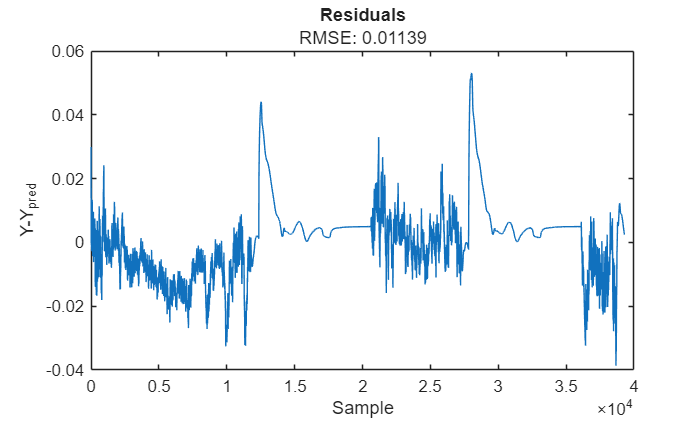

testFile = fullfile(dataFolder,"Test","01_TEST_LGHG2@n10degC_Norm_(05_Inputs).mat");
S = load(testFile);

XTest = S.X(1:numFeatures,:)';
YTest = S.Y;

YPredProjected = predict(recurrentNetProjected, XTest);

[RMSEProjectedNN,residualsProjectedNN] = rmse(YTest,YPredProjected);

figure
plot(residualsProjectedNN);
title("Residuals","RMSE: " + RMSEProjectedNN)
xlabel("Sample")
ylabel("Y-Y_{pred}")

% Calculate network accuracy
1 - RMSEProjectedNN

ans = single
0.9886

16.Generate Code from Deep Learning Models

Open the model:

open_system("SOC_model_Code_Gen");

Open the **Configuration Parameters** dialog (or Ctrl+E) and set **Simulation Target **to **C**

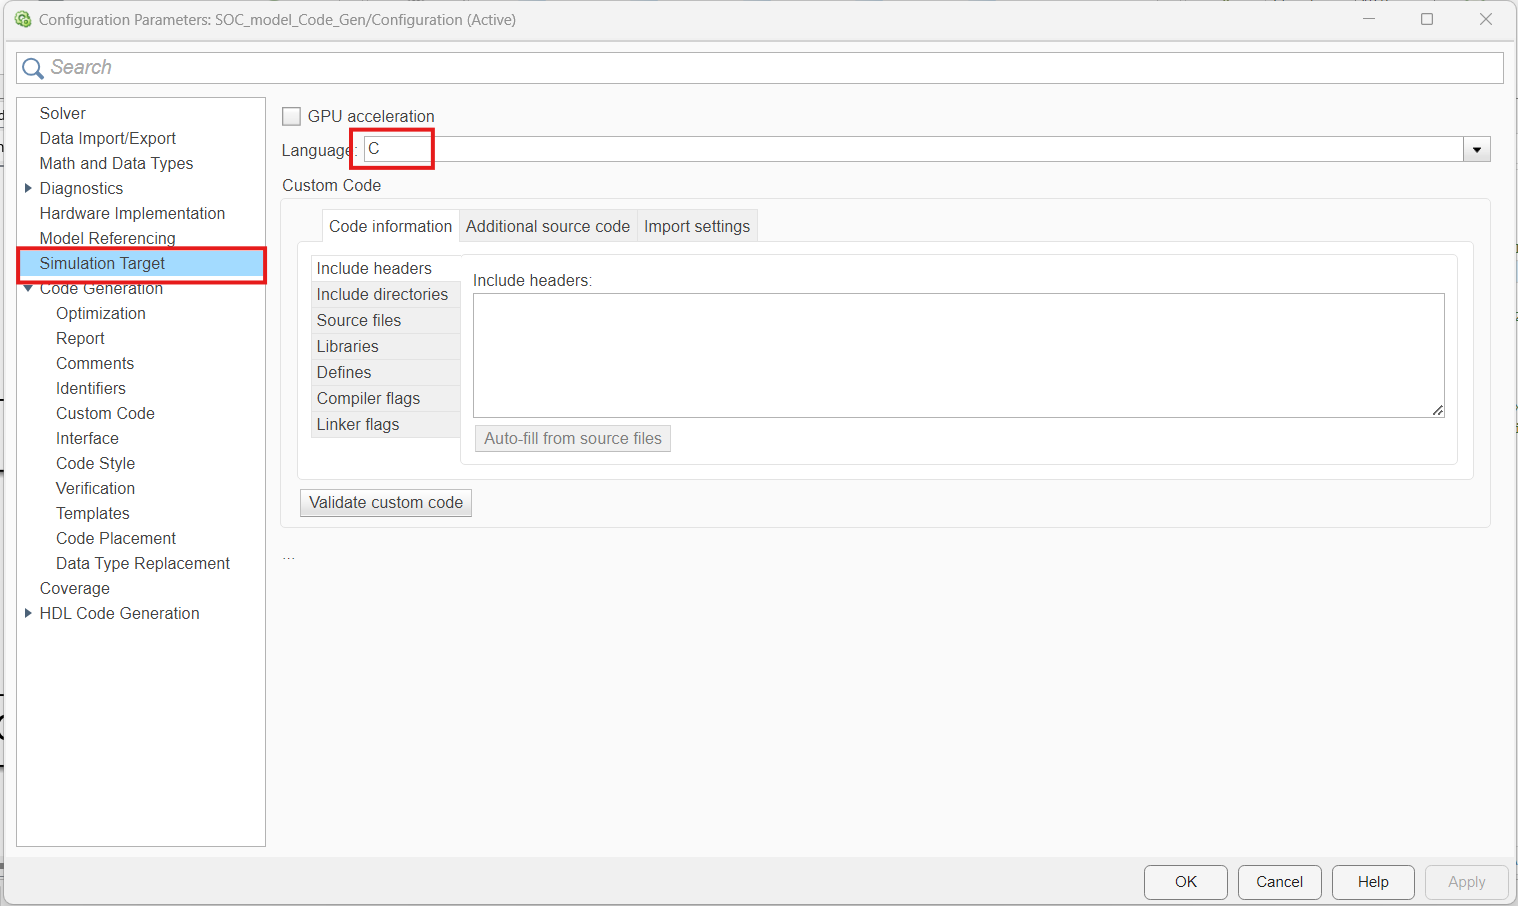

Uncheck the "**Enable portable word sizes**"

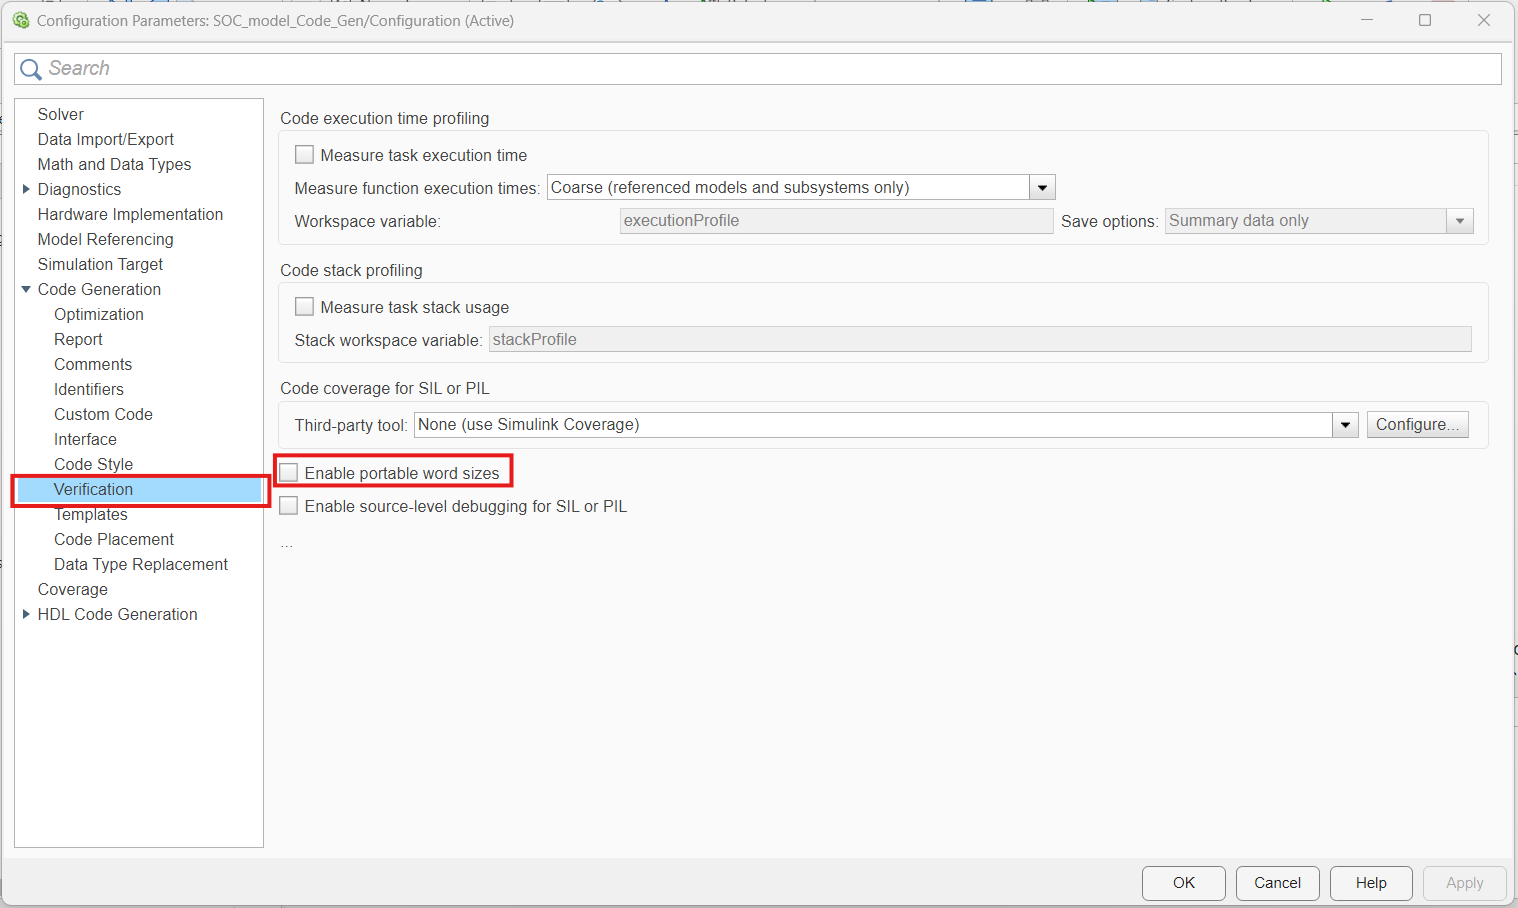

To generate code from the **AI subsystem** and inspect the **Static Code Metrics** Report:

- Right-click the **AI Subsystem**

- Select **C/C++ Code** > **Build This Subsystem**.

Optional: here are the configuration steps that have been set up for you for your reference. These configurations have been saved with the model.

- Click into the **AI** **subsystem** and apply the same settings for both LSTM and LSTM Projected subsystems. On the **Subsystem Block** pane, under **Component**, click **Atomic Subsystem**. Right-click the subsystem, and select **Block Parameters** **(subsystem)**. In the **Code Generation** tab, set **Function Packaging** to **Nonreusable function**.

- Open the Configuration Parameters dialog box. In the Simulink Editor, on the **Modeling** tab, click **Model Settings**.

- On the **Code Generation** pane, under **Target selection**, specify the system target file as `ert.tlc`.

- Under **Build process**, uncheck **Generate code only**

- On the **Code Generation **> **Optimization** pane, set **Leverage target hardware instruction set extensions **to **None**

17.Inspect Generated Code

Click "Open Report" on the "C Code" tab on the Simulink Toolstrip.

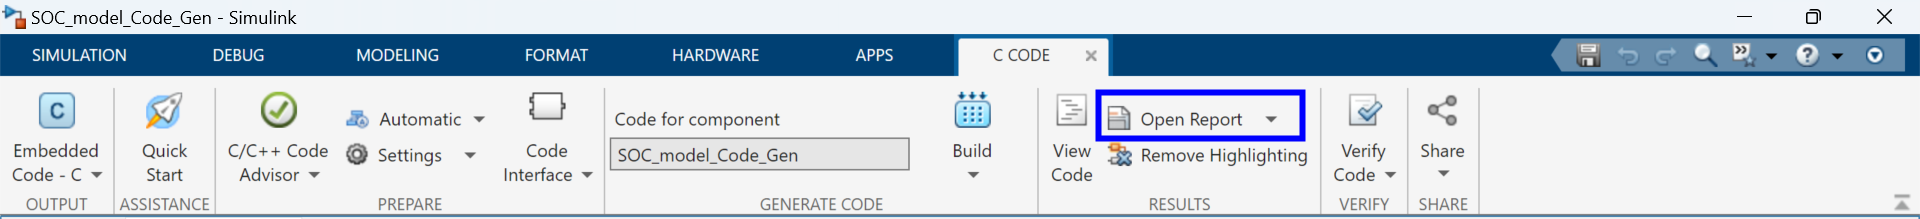

After the **Code Generation Report** window opens, in the "Code" section on the left-hand side panel, click through the "Model files" to inspect the content of the code.

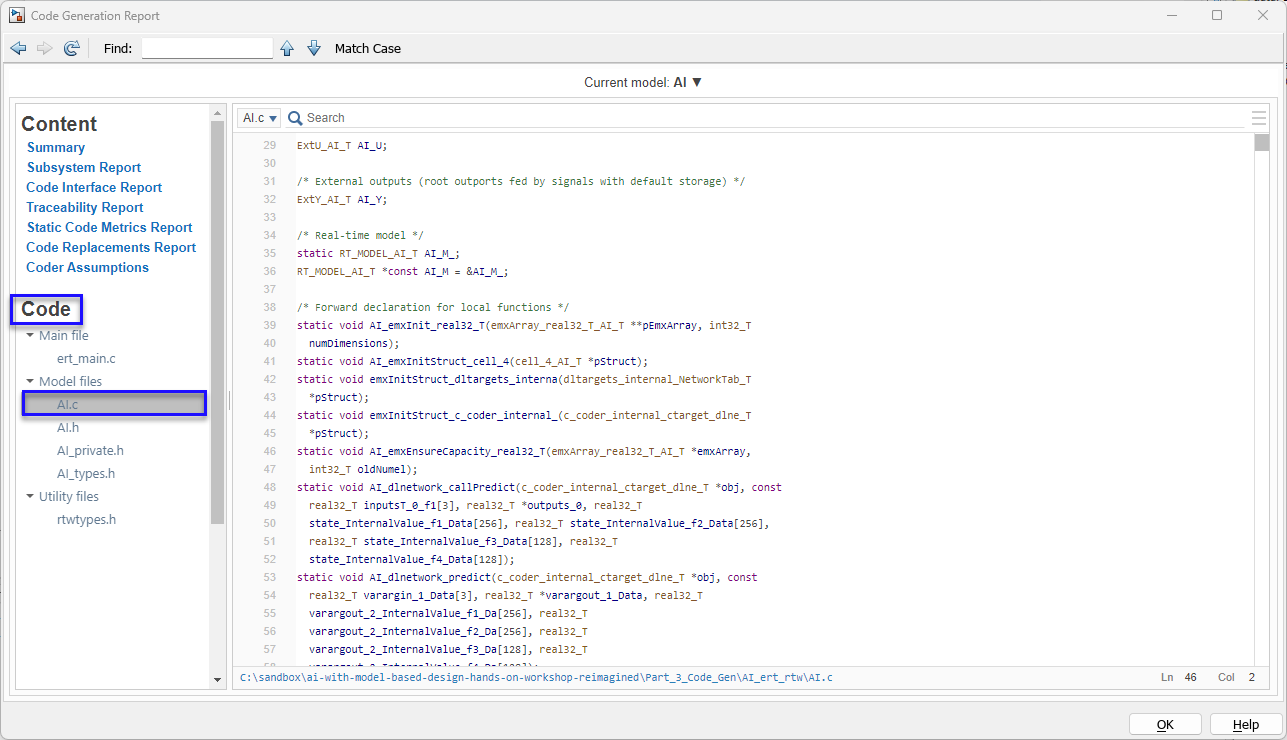

Root mean squared error helper function

function [rmseValue,residuals] = rmse(y,t)
    residuals = y(:)-t(:);
    rmseValue = sqrt(mean(residuals.^2));
end